## Modeling World Population Growth

### Introduction

In 1968 Paul Erlich published *The Population Bomb*, in which he predicted that world population would grow quickly during the 1970s, that agricultural production could not keep up, and that mass starvation in the next two decades was inevitable (see [https://en.wikipedia.org/wiki/The_Population_Bomb](https://en.wikipedia.org/wiki/The_Population_Bomb)).  As someone who grew up during those decades, I am happy to report that those predictions were wrong.

But world population growth is still a topic of concern, and it is an open question how many people the earth can sustain while maintaining and improving our quality of life.

In this case study, we use simple models to explain world population growth since 1950 and generate predictions for the next 50--100 years.

For background on world population growth, watch this video from the American Museum of Natural History: [https://www.youtube.com/watch?v=PUwmA3Q0_OE.](https://www.youtube.com/watch?v=PUwmA3Q0_OE.)

clear all

### Data

The Wikipedia article on world population estimates ([https://en.wikipedia.org/wiki/World_population_estimates](https://en.wikipedia.org/wiki/World_population_estimates)) summarizes data from the United Nation and U.S. Census Bureau, which I have converted to CSV files.

Here's the data from the UN Department of Economic and Social Affairs (DESA):

filename = '../data/world_pop_un.csv';
m = readmatrix(filename);
years = m(:,1)'

years =         1950        1951        1952        1953        1954        1955        1956        1957        1958        1959        1960        1961        1962        1963        1964        1965        1966        1967        1968        1969        1970        1971        1972        1973        1974        1975        1976        1977        1978        1979        1980        1981        1982        1983        1984        1985        1986        1987        1988        1989        1990        1991        1992        1993        1994        1995        1996        1997        1998        1999


un = m(:,2)'

un =     2.5251    2.5729    2.6193    2.6659    2.7132    2.7617    2.8116    2.8630    2.9160    2.9704    3.0260    3.0828    3.1411    3.2012    3.2637    3.3291    3.3975    3.4685    3.5417    3.6161    3.6912    3.7668    3.8429    3.9192    3.9953    4.0710    4.1461    4.2208    4.2957    4.3715    4.4490    4.5282    4.6090    4.6916    4.7764    4.8636    4.9534    5.0453    5.1382    5.2300    5.3208    5.4089    5.4949    5.5789    5.6611    5.7418    5.8210    5.8987    5.9753    6.0515


And from the U.S. Census Bureau:

filename = '../data/world_pop_census.csv';
m = readmatrix(filename);
census = m(:,2)'

census =     2.5576    2.5949    2.6368    2.6821    2.7302    2.7821    2.8353    2.8913    2.9481    3.0007    3.0430    3.0840    3.1401    3.2098    3.2812    3.3504    3.4207    3.4903    3.5623    3.6372    3.7127    3.7903    3.8666    3.9421    4.0166    4.0891    4.1602    4.2321    4.3041    4.3790    4.4514    4.5344    4.6146    4.6957    4.7746    4.8565    4.9406    5.0272    5.1146    5.2014    5.2890    5.3716    5.4561    5.5383    5.6187    5.6992    5.7794    5.8580    5.9352    6.0121


### Constant growth model

Suppose we want to predict world population growth over the next 50 or 100 years.  We can do that by developing a model that describes how populations grow, fitting the model to the data we have so far, and then using the model to generate predictions.

I will demonstrate this process starting with simple models and gradually improving them.

Although there is some curvature in the plotted estimates, it looks like world population growth has been close to linear since 1960 or so.  So we'll start with a model that has constant growth.

To fit the model to the data, I'll compute the average annual growth from 1950 to 2016.  Since the UN and Census data are so close, I'll use the Census data.

Here are the first and last elements of the series (in billions):

system.p_0 = census(1);
system.p_end = census(end);

And here is the elapsed time in years:

system.t_0 = years(1);
system.t_end = years(end);
system.elapsed_time = system.t_end - system.t_0;

 Then we can compute the average annual growth in billions of people per year.

total_growth = system.p_end - system.p_0

total_growth = 4.7684

system.annual_growth = total_growth / system.elapsed_time;
system.years = years;
system

system = struct with fields:
              p_0: 2.5576
            p_end: 7.3260
              t_0: 1950
            t_end: 2016
     elapsed_time: 66
    annual_growth: 0.0722
            years: [1×67 double]


results = run_simulation(system, @constant_growth_update);

results =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


res =     2.5576    2.6299    2.7021    2.7744    2.8466    2.9189    2.9911    3.0634    3.1356    3.2079    3.2801    3.3524    3.4246    3.4969    3.5691    3.6413    3.7136    3.7858    3.8581    3.9303    4.0026    4.0748    4.1471    4.2193    4.2916    4.3638    4.4361    4.5083    4.5806    4.6528    4.7251    4.7973    4.8696    4.9418    5.0141    5.0863    5.1586    5.2308    5.3031    5.3753    5.4475    5.5198    5.5920    5.6643    5.7365    5.8088    5.8810    5.9533    6.0255    6.0978


Here's what the results looks like, compared to the actual data.

data.year = years;
data.un = un;
data.census = census;
data

data = struct with fields:
      year: [1×67 double]
        un: [1×67 double]
    census: [1×67 double]


results

results =     2.5576    2.6299    2.7021    2.7744    2.8466    2.9189    2.9911    3.0634    3.1356    3.2079    3.2801    3.3524    3.4246    3.4969    3.5691    3.6413    3.7136    3.7858    3.8581    3.9303    4.0026    4.0748    4.1471    4.2193    4.2916    4.3638    4.4361    4.5083    4.5806    4.6528    4.7251    4.7973    4.8696    4.9418    5.0141    5.0863    5.1586    5.2308    5.3031    5.3753    5.4475    5.5198    5.5920    5.6643    5.7365    5.8088    5.8810    5.9533    6.0255    6.0978


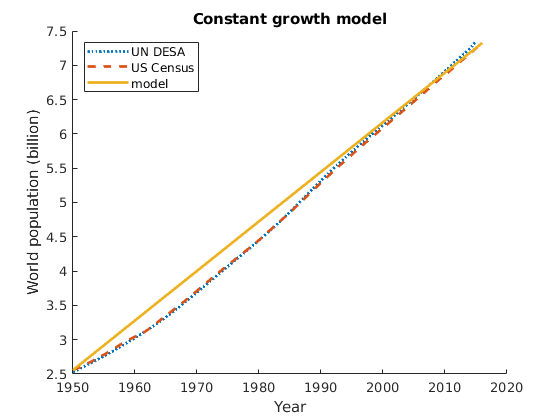


plot_results(results, data)

function res = constant_growth_update(t, y, system)
    % Compute the population next year.
    
    % t: current year
    % pop: current population
    % system: structure containing parameters of the model
    
    % returns: population next year
    res = y + system.annual_growth;
end

function res = update_func2(t, y, system)
    % Compute the population next year.
    
    % pop: current population
    % t: current year
    % system: system object containing parameters of the model
    
    % returns: population next year
    births = system.birth_rate * y
    deaths = system.death_rate * y
    res = y + births - deaths
end


function res = run_simulation(system, update_func)
    results = zeros(size(system.years))
    results(1) = system.p_0;
    for i = 1:length(results)-1
        t = system.years(i);
        results(i+1) = update_func(t, results(i), system);
    end
    res = results
end


function res = plot_results(results, data)
    clf; hold on

    plot(data.year, data.un, ':', 'LineWidth', 2)
    plot(data.year, data.census, '--', 'LineWidth', 2)
    plot(data.year, results, 'LineWidth', 2)
    legend('UN DESA', 'US Census', 'model', 'Location', 'northwest')

    xlabel('Year') 
    ylabel('World population (billion)')
    title('Constant growth model')
end